# 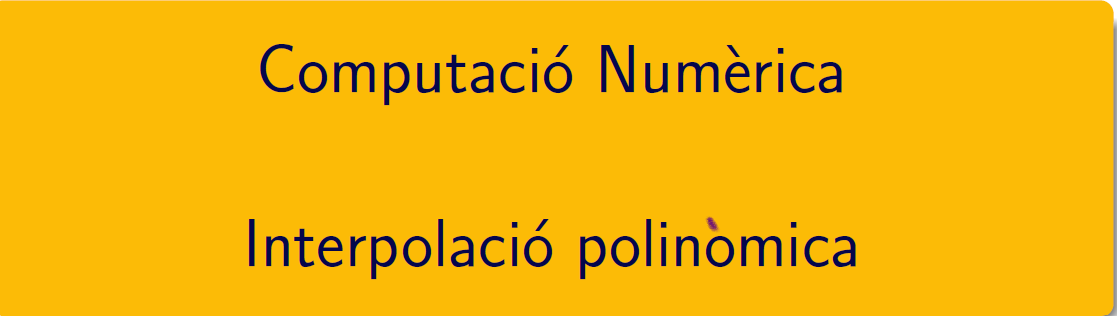

================================================================================

# Pràctica 9. Interpolació polinòmica i ajust de dades

## Introducció

A més a més dels exercicis d'aquest script teniu disponibles exercicis en el document Guia-Lab9.pdf i en el document CN_full6.pdf, els podeu trobar en el campus virtual. 

## 1 APRENEM .....

### Polinomis i MATLAB®

Consulteu la pàgina [crear y evaluar polinomios](https://es.mathworks.com/help/matlab/math/create-and-evaluate-polynomials.html) y la pàgina [Raíces de polinomios](https://es.mathworks.com/help/matlab/ref/roots.html), ambdues de la documentació de MATLAB®. També us pot interesar la pàgina [Integrar y diferenciar polinomios](https://es.mathworks.com/help/matlab/math/integrate-and-differentiate-polynomials.html).

Després de llegir els dos primers documents, calculeu:

- les arrels del polinomi cúbic (grau 3)  $x^3+4x^2+4x=0$ 

p=[1 4 4 0];                       % vector amb els coeficients del polinomi 
r=roots(p); 
disp(['arrels = ', num2str(r')])   % arrels

arrels = 0 -2 -2


- avalueu el polinomi  $x^5-1$ per $x=2$

p=[1 0 0 0 0 -1 ];                 % vector amb els coeficients del polinomi 
v=polyval(p,2); 
disp(['valor = ',num2str(v)])      % valor polinomi

valor = 31


- coficients del polinomi d'arrels els enters  -5,-2, -1, 1, 2, i 8. Quin grau té?

r=[-5,-2,-1,1,2,8 ];               % vector amb les arrels
c=poly(r); 
disp(['coeficients = ',num2str(c)])   % coeficients polinomi d'arrels r

coeficients = 1   -3  -45   15  204  -12 -160


### Polinomi interpolador

Baixeu-vos del campus el codi de polyinterp.m. Aquest codi és el que C. Moler explica en el chapter 3 dels seus apunts *"Numerical Computing with Matlab". *Consulteu la pàgina 5 i reproduïu el seu exemple. 

x = 1:6;
y = [16 18 21 17 15 12];
disp([x; y])

     1     2     3     4     5     6
    16    18    21    17    15    12



polyinterp(x,y,4.5)

ans =        15.316


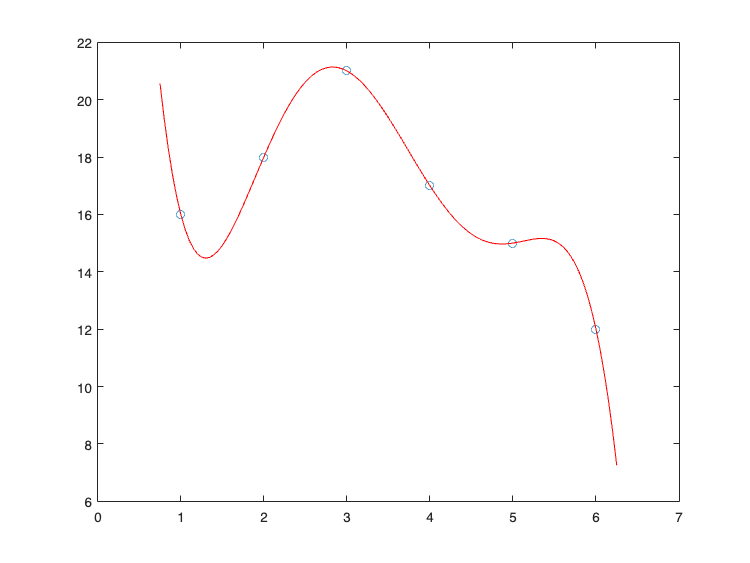

u = .75:.05:6.25;
v = polyinterp(x,y,u);   
plot(x,y,'o',u,v,'r-');

La rutina polyinterp.m obté els valors del polinomi interpolador (fórmula de Lagrange) de la taula [x;y] i permet fer la seva representació gràfica. En cap cas obtenim els coeficients del polinomi interpolador.

#### Funcions de MATLAB® 

Els coeficients del polinomi interpolador es poden obtenir amb polyfit, i els valors aproximats amb polyval. Consulteu [polyfit](https://es.mathworks.com/help/matlab/ref/polyfit.html)

x = 1:6;
y = [16 18 21 17 15 12];
disp([x; y])

     1     2     3     4     5     6
    16    18    21    17    15    12



grau = length(x)-1

grau =      5


p = polyfit(x,y,grau)  

p =      -0.24167       4.3333      -28.958       87.667       -115.8           69


polyval(p,4.5)                         

ans =        15.316


**polyinterp de Moler = polyfit + polyval de MATLAB**

### Interpolació polinomial a trossos. 

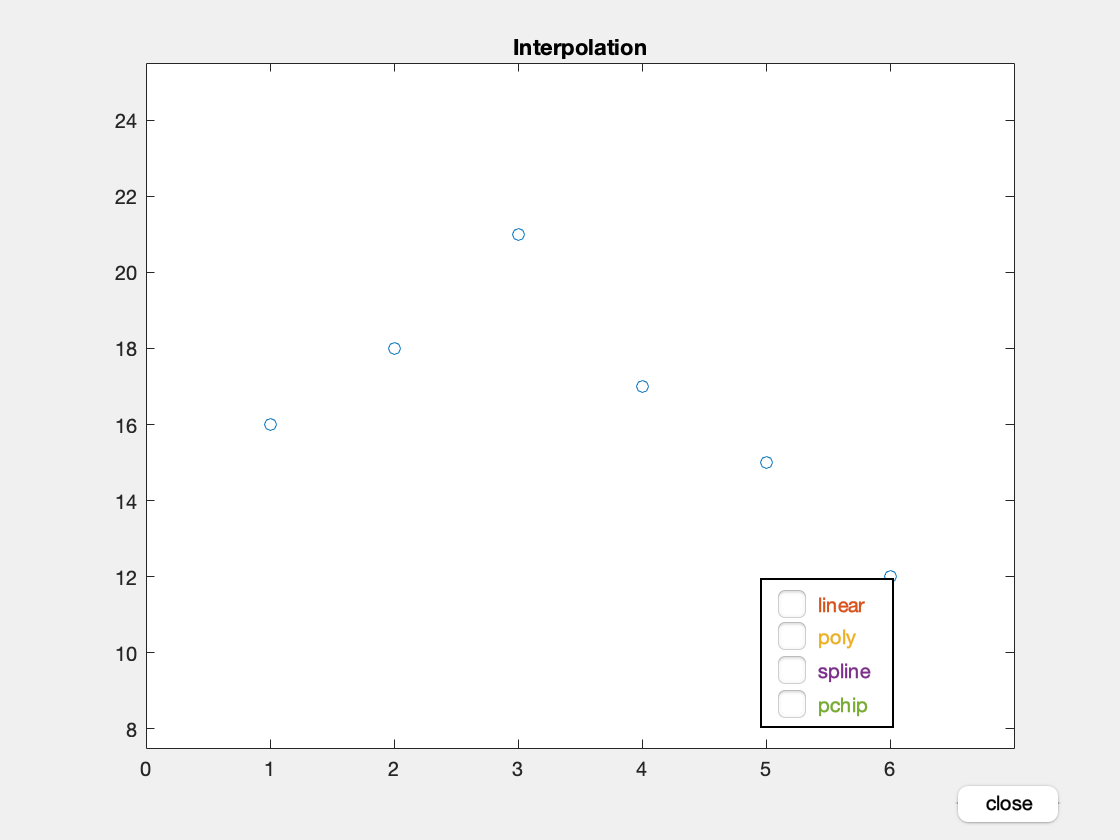

Unrecognized function or variable 'piecelin'.

Error in Prac9_28Abril_grup1>interpgui (line 337)
set(p(2),'xdata',u,'ydata',piecelin(x,y,u));

clearvars; 
x = 1:6;
y = [16 18 21 17 15 12];
interpgui(x,y)

#### Diferències entre spline i pchip

clearvars;
x = 1: 8;
y = zeros (1,8);
y (4) = 1;
interpgui(x, y)

#### Funcions de MATLAB® 

Per veure totes les possibilitats d'interpolació en MATLAB® consulteu la pàgina [interpolación](https://es.mathworks.com/help/matlab/interpolation.html) y més concretament la pàgina de la comanda [interp1](https://es.mathworks.com/help/matlab/ref/interp1.html), per obtenir un polinomi interpolador a trossos. Resum de de la comanda. 

Baixeu-vos del campus ***InterpolationofCoarselySampledSineFunctionExample.mlx, ***és el primer exemple de la documentació. Apreneu com s'usa la comanda interp1 per a obtenir els valors de l'spline lineal i els valors de l'spline cúbic. 

% openExample('matlab/InterpolationofCoarselySampledSineFunctionExample')

#### Interpolació i extrapolació

Baixeu-vos del campus ***ExtrapolationUsingTwoDifferentMethodsExample.mlx*** . Aquest codi és de la documentació. Apreneu com s'usa la comanda interp1 per a obtenir els valors de l'spline per avaluar punts que es troben fora del domini de x.

% openExample('matlab/ExtrapolationUsingTwoDifferentMethodsExample')

## 2 PRACTIQUEM ....

clearvars; clf; format shortG

### 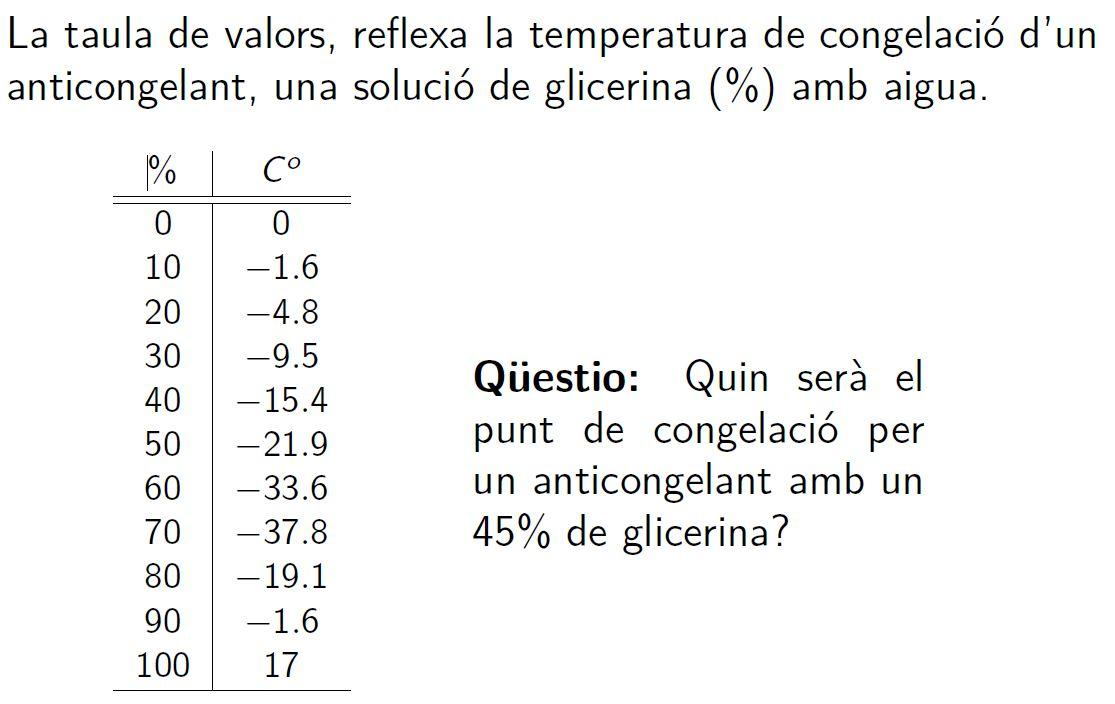

### Enunciat

Donar una estimació del punt de congelació per anticongelant amb **45%** de glicerol. Aquest exercici s'ha de resoldre fent ús de **polyinterp.**

- Gráfica de los datos

x=0:10:100; 
y=[0 -1.6 -4.8 -9.5 -15.4 -21.9 -33.6 -37.8 -19.1 -1.6 17];
plot(x,y,'*')

grid on
ylabel('Temperatura, ºC')
xlabel('% Glicerina')

#### Exercici 1. Interpolació lineal (recta)

- Valor aproximat polinomi

x1=[40, 50];
y1=[-15.4 -21.9];
valor_p1_45=polyinterp(x1,y1,45)

disp(['valor = ',num2str(valor_p1_45)])

- Grafica de les dades, el valor aproximat i el polinomi interpolador

z=[25:65]; 
pz=polyinterp(x1,y1,z);
plot(z,pz,x,y,'*b',45,valor_p1_45,'*r','LineWidth',2)

grid on
ylabel('Temperatura, ºC')
xlabel('% Glicerina')
title('Recta')

#### Exercici 2. Polinomi interpolador de grau 3

- Valor aproximat polinomi

- Grafica de les dades, el valor aproximat i el polinomi interpolador

x = 0:10:100; 
y = [0 -1.6 -4.8 -9.5 -15.4 -21.9 -33.6 -37.8 -19.1 -1.6 17];

x2=[30, 40, 50, 60];
y2=[-9.5 -15.4 -21.9 -33.6];
valor_p3_45=polyinterp(x2,y2,45)
p3 = polyfit(x2,y2,3)

disp(['valor = ',num2str(valor_p3_45)])
z=[25:65]; 
pz=polyinterp(x2,y2,z);
plot(z,pz,x,y,'*b',45,valor_p3_45,'*r','LineWidth',2)

grid on
ylabel('Temperatura, ºC')
xlabel('% Glicerina')
title('Cúbica')

#### Exercici 3. Polinomi interpolador de grau 10

- Valor aproximat polinomi

- Grafica de les dades, el valor aproximat i el polinomi interpolador

x=0:10:100; 
y=[0 -1.6 -4.8 -9.5 -15.4 -21.9 -33.6 -37.8 -19.1 -1.6 17];

valor_p10_45=polyinterp(x,y,45);
disp(['valor = ',num2str(valor_p10_45)])
z=[0:100]; 
pz=polyinterp(x,y,z);
plot(z,pz,x,y,'*b',45,valor_p10_45,'*r','LineWidth',2)

grid on
ylabel('Temperatura, ºC')
xlabel('% Glicerina')
title('Polinomi grau 10')

#### Exercici 4. Spline lineal  (interpolació lineal a trossos)

- Valor aproximat polinomi

- Grafica de les dades, el valor aproximat i el polinomi interpolador

x=0:10:100; 
y=[0 -1.6 -4.8 -9.5 -15.4 -21.9 -33.6 -37.8 -19.1 -1.6 17];

valor_sl_45=interp1(x,y,45);
disp(['valor = ',num2str(valor_sl_45)])
z=[0:100]; 
pz=interp1(x,y,z);
plot(z,pz,x,y,'*b',45,valor_sl_45,'*r','LineWidth',2)

grid on
ylabel('Temperatura, ºC')
xlabel('% Glicerina')
title('Spline lineal')

#### Exercici 5. Spline cúbic  (interpolació cúbica a trossos)

- Valor aproximat polinomi

- Grafica de les dades, el valor aproximat i el polinomi interpolador

x=0:10:100; 
y=[0 -1.6 -4.8 -9.5 -15.4 -21.9 -33.6 -37.8 -19.1 -1.6 17];

valor_sl_45=interp1(x,y,45,"spline");
disp(['valor = ',num2str(valor_sl_45)])

z=[0:100]; 
pz=interp1(x,y,z,'spline');
plot(z,pz,x,y,'*b',45,valor_sl_45,'*r','LineWidth',2)

grid on
ylabel('Temperatura, ºC')
xlabel('% Glicerina')
title('Spline natural')

valor_sl_45=interp1(x,y,45,"pchip");
disp(['valor = ',num2str(valor_sl_45)])

z=[0:100]; 
pz=interp1(x,y,z,'pchip');
plot(z,pz,x,y,'*b',45,valor_sl_45,'*r','LineWidth',2)

grid on
ylabel('Temperatura, ºC')
xlabel('% Glicerina')
title('Spline pchip')

#### Exercici 6. Ajust per mínims quadrats (recta)

- Valor aproximat recta

- Grafica de les dades, el valor aproximat i el polinomi interpolador

clearvars;
x=0:10:100; 
y=[0 -1.6 -4.8 -9.5 -15.4 -21.9 -33.6 -37.8 -19.1 -1.6 17];

r=polyfit(x,y,1)
r_45 = polyval(r,45)
z=[0:100]; 
pz=polyval(r,z);
plot(z,pz,x,y,'*b',45,r_45,'*r','LineWidth',2)

grid on
ylabel('Temperatura, ºC')
xlabel('% Glicerina')
title('recta mínins')

#### Exercici 7. Ajust per mínims quadrats (cúbica)

- Valor aproximat cúbica

- Grafica de les dades, el valor aproximat i el polinomi interpolador

clearvars;
x=0:10:100; 
y=[0 -1.6 -4.8 -9.5 -15.4 -21.9 -33.6 -37.8 -19.1 -1.6 17];

q=polyfit(x,y,2)
q_45 = polyval(q,45)
z=[0:100]; 
pz=polyval(q,z);
plot(z,pz,x,y,'*b',45,q_45,'*r','LineWidth',2)

grid on
ylabel('Temperatura, ºC')
xlabel('% Glicerina')
title('Cúbica mínins')

#### Exercici 8. Interpolació des de la finestra de gràfics

Representeu gràficament la taula de dades, cada node per un *, a continuació mitjançant el menú Tools de la finestra gràfica accediu a l'opció basic fitting i trobeu una corba que ajusti les dades.

clearvars;
x=0:10:100; 
y=[0 -1.6 -4.8 -9.5 -15.4 -21.9 -33.6 -37.8 -19.1 -1.6 17];

### Exercici 9. Interpolació inversa

Aplicació de la interpolació al càlcul de zeros de funcions.

clearvars;
f=@(x)x-cos(x); 
fplot({f,0},[-2,2],'LineWidth',2),grid,legend('Location','bestoutside')
raiz = fzero(f,1)
xnodes = [0.5,0.75,1.25];
ynodes = f(xnodes)
disp([xnodes;ynodes]')
arrel = polyinterp(ynodes,xnodes,0)
arrel = interp1(ynodes,xnodes,0,'pchip')

### Exercici 10. Extrapolació

Què s'enten per extrapolació?

Exemple de Cleve Moler, [Census 2017](https://es.mathworks.com/company/newsletters/articles/fitting-and-extrapolating-u-s-census-data.html) i [Census 2020](https://blogs.mathworks.com/cleve/2020/11/06/anticipating-official-u-s-census-for-2020/)

clf, clearvars, format short g
load dades.mat
disp([cdate,pop])
plot(cdate,pop,'*')

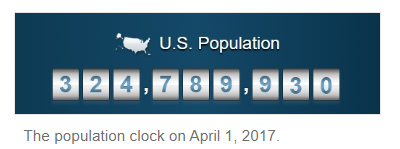

valor_lineal = interp1(cdate,pop,2017,'linear','extrap')
valor_polinomi = polyinterp(cdate,pop,2017)
valor_spline = interp1(cdate,pop,2017,'spline')
valor_pchip = interp1(cdate,pop,2017,'pchip')

## 3 Codi funcions: polyinterp 

Baixeu-vos del campus el codi de polyinterp.m. Aquest codi és el que C. Moler explica en el chapter 3 dels seus apunts *"Numerical Computing with Matlab"  (*pàgina 5). 

La rutina polyinterp.m obté els valors del polinomi interpolador (fórmula de Lagrange) de la taula [x;y] i permet fer la seva representació gràfica. En cap cas obtenim els coeficients del polinomi interpolador. 

function v = polyinterp(x,y,u)
%POLYINTERP  Polynomial interpolation.
%   v = POLYINTERP(x,y,u) computes v(j) = P(u(j)) where P is the
%   polynomial of degree d = length(x)-1 with P(x(i)) = y(i).

%   Copyright 2014 Cleve Moler
%   Copyright 2014 The MathWorks, Inc.

% Use Lagrangian representation.
% Evaluate at all elements of u simultaneously.

n = length(x);
v = zeros(size(u));
for k = 1:n
   w = ones(size(u));
   for j = [1:k-1 k+1:n]
      w = (u-x(j))./(x(k)-x(j)).*w;
   end
   v = v + w*y(k);
end
end

function interpgui(arg1,arg2)
%INTERPGUI  Behavior of interpolating functions.
%   Demonstrates interpolation by a piecewise linear interpolant,
%   a polynomial, a spline, and a shape preserving Hermite cubic.
%   INTERPGUI(x,y) starts with a plot of y vs. x.
%   INTERPGUI(y) starts with equally spaced x's.
%   INTERPGUI(n) starts with y = zeros(1,n).
%   INTERPGUI with no arguments starts with eight zeros.
%   The interpolation points can be varied with the mouse.
%   If x is specified, it remains fixed.
%
%   See also SPLINETX, PCHIPTX, POLYINTERP, PIECELIN.

%   Copyright 2014 Cleve Moler
%   Copyright 2014 The MathWorks, Inc.

if nargin == 0 | isnumeric(arg1)

   % Interpret arguments

   if nargin == 0
      % interpgui with no arguments
      n = 8;
      x = 1:n;
      y = zeros(1,n);
   elseif length(arg1) == 1
      % interpgui(n)
      n = arg1;
      x = 1:n;
      y = zeros(1,n);
   elseif nargin == 1
      % interpgui(y)
      n = length(arg1);
      x = 1:n;
      y = arg1(:)';
   elseif length(arg1) == length(arg2)
      % interpgui(x,y)
      [x,k] = sort(arg1(:)');
      y = arg2(k)';
   else
      error('Two arguments must have same length')
   end
   arg1 = [];

   % Initialize figure

   shg
   clf reset
   set(gcf,'name','Interpgui','numbertitle','off','menu','none', ...
     'windowbuttondown',['interpgui(''move''); set(gcf,' ...
        '''windowbuttonmotion'',''interpgui(''''move'''')'')'], ...
     'windowbuttonup','set(gcf,''windowbuttonmotion'','''')');

   % Initialize plots

   n = length(x);
   h = diff(x);
   u = zeros(1,128*(n+1));
   j = 1:128;
   s = (1+sin((j-65)/128*pi))/2;
   u(j) = x(1)+(s-1)*h(1);
   for k = 1:n-1
      u(128*k+j) = x(k)+s*h(k);
   end
   u(128*n+j) = x(n)+s*h(n-1);
   p = plot(x,y,'o',u,zeros(4,length(u)),'-');
   ymin = min(y);
   ymax = max(y);
   ydel = ymax-ymin;
   if ydel == 0; ydel = 1; end
   axis([min(u) max(u) ymin-0.5*ydel ymax+0.5*ydel])
   title('Interpolation')

   % Controls

   uicontrol('units','normal','pos',[.68 .13 .12 .18], ...
     'style','frame','background','white')
   F = {'linear','poly','spline','pchip'};
   pos = [.69 .26 .09 .04];
   vis = 0;
   for k = 1:4
      uicontrol('units','normal','pos',pos, ...
         'style','check','string',F{k},'value',vis, ...
         'background','white','foreground',get(p(k+1),'color'), ...
         'callback','interpgui(''cb'')');
      pos(2) = pos(2)-.04;
   end
   uicontrol('units','normal','pos',[.85 .01 .10 .06], ...
      'style','push','string','close','tag','reset/close', ...
      'callback','close(gcf)');

   % Remember original data

   xfree = (nargin < 2);
   set(gcf,'userdata',xfree)
   set(gca,'userdata',{x,y})
end

p = flipud(get(gca,'children'));
x = get(p(1),'xdata');
y = get(p(1),'ydata');
n = length(x);
h = diff(x);
u = zeros(1,128*(n+1));
j = 1:128;
s = (1+sin((j-65)/128*pi))/2;
u(j) = x(1)+(s-1)*h(1);
for k = 1:n-1
   u(128*k+j) = x(k)+s*h(k);
end
u(128*n+j) = x(n)+s*h(n-1);

if isequal(arg1,'reset')

   % Restore original data

   xy = get(gca,'userdata');
   x = xy{1};
   y = xy{2};
   set(findobj('tag','reset/close'),'string','close', ...
      'callback','close(gcf)');

elseif isequal(arg1,'move')

   % Respond to mouse motion

   z = get(gca,'currentpoint');
   z = z(1,:);
   p = flipud(get(gca,'children'));
   e = abs(x-z(1));
   k = min(find(e == min(e)));
   xfree = get(gcf,'userdata');
   if xfree
      x(k) = z(1);
   end
   y(k) = z(2);
   set(findobj('tag','reset/close'),'string','reset', ...
      'callback','interpgui(''reset'')');

end

ax = axis;
set(p(1),'xdata',x,'ydata',y)
set(p(2),'xdata',u,'ydata',piecelin(x,y,u));
set(p(3),'xdata',u,'ydata',polyinterp(x,y,u));
set(p(4),'xdata',u,'ydata',splinetx(x,y,u));
set(p(5),'xdata',u,'ydata',pchiptx(x,y,u));
axis(ax);

% Visibility

b = flipud(get(gcf,'children'));
onf = {'off','on'};
for k = 1:4
   % Interpolants
   set(p(k+1),'visible',onf{get(b(k+2),'value')+1})
end
end